## Intro

This document outlines the design of a spring hinge using a conventional pivot and torsional springs. Using proper coil-wound torsional springs avoids the issues of a single-piece compliant hinge analyzed in Dossier 8.

The images below show the hinge and the loads applied to the antenna is supports. 

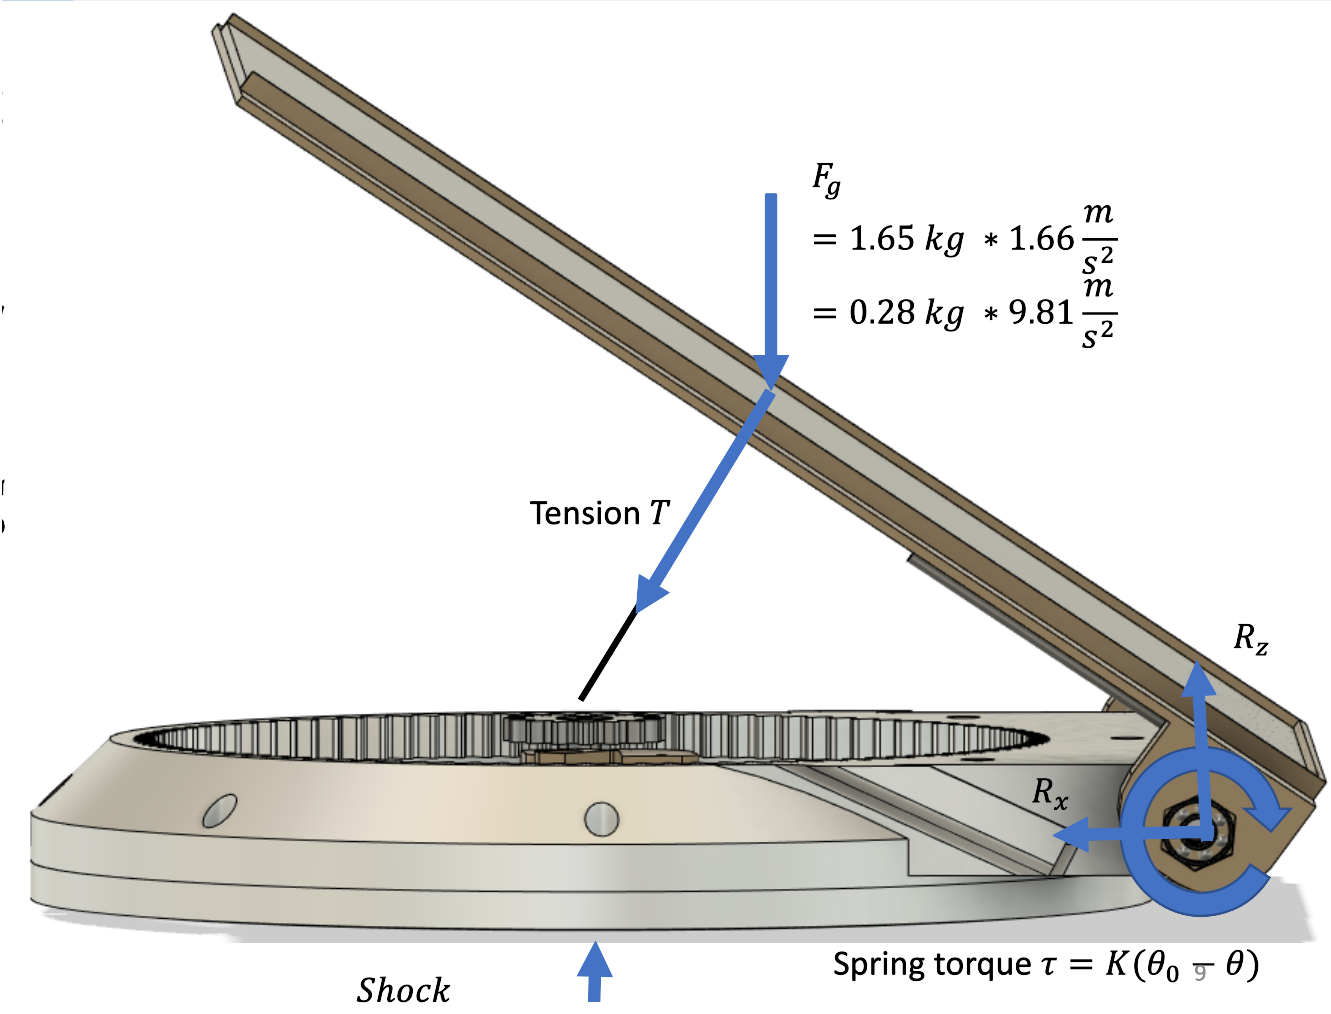

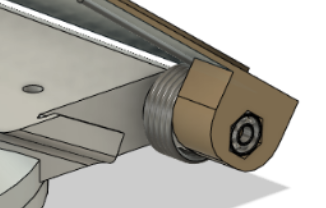

The goal of this anaylsis is to determine which torsional springs to buy, based on their relative performance in:

- Power consumed by the winch to pull the antenna down (an overall design performance criteria)

- Tension preload in cable, which improves performance under shock loads

- Excess lifiting ability; the hinge's ability to lift things larger than just the antenna, including the dust cover or overcoming friction

First, define the mass parameters in the problem of the antenna.

%mechsys dynamics
close all
g = 1.62; %m/s2, gravity on moon/earth
m = 1.65; %kg, antenna mass

L = 0.290; %m, antenna length
realI = 1/3.*m.*L.^2; %kg m2, moment of inertia

Next, define the options available for torsional springs. On McMaster-Carr, the easiest supplier for prototyping, torsional springs are categorized by their maximum torque at fully deformed and undeformed angle. For more details, see [https://www.mcmaster.com/torsion-springs/torsion-springs-5/](https://www.mcmaster.com/torsion-springs/torsion-springs-5/) 

T_in = linspace(0.1, 80, 20);
theta0_in = [360, 270, 225, 180, 120] * pi/180;
[T, theta0] = meshgrid(T_in, theta0_in); %undeformed spring angle, in radians; max spring load in in-lbs. These are values provided by mcmc

%find spring constant in Nm/rad for calculations
K = T*0.11298482933333./theta0;

The simple mechanical bandiwdth - with no tension in the cable - is calculated below

BW = sqrt(K./realI);

## Power

Next, find the power consumption of the motor at 0 (flat) and 90 (vertical) degrees of antenna elevation.


% motor characteristics
% not looking at any dynamics, just the "stall torque" and current required
% to hold a given spring at fully retracted. 

V = 12; %volts, motor voltage
T_max = 0.8; % Nm, based on stall torque in datasheet.
I_max = 0.6; % A, based on stall current in datasheet

The aforementioned datasheet for the motor is linked here:

[https://www.nidec-copal-electronics.com/e/catalog/dc-geared-motor/mg16b.pdf](https://www.nidec-copal-electronics.com/e/catalog/dc-geared-motor/mg16b.pdf) 

The model number is MG16B-300-AB-00 by Nidec Copal Electronics

pulley_radius = 0.007; % mm, pulley radius

The maximum and minimum tension - at 0 and 90 degrees elevation, respectively, are calculated below. It is based on the free body diagram above. Note that depending on the undeformed angle of the spring, these may not correspond to the minimum and maximum torques, but do for the range of springs analyzed.

tension_min = (theta0 - pi/2).*K./(L/2*sin(pi/4)); %N, min cable tension, at top, but not perpendicular to plane. No gravity torque 
tension_max = ((theta0).*K - m.*g.*L/2)./(L/2); %N, max cable tension, at bottom, supported by gravity.
motor_torque_max = tension_max*pulley_radius; % Nm, torque required to hold antenna full closed
motor_torque_min = tension_min*pulley_radius;

The maximum and minimum motor current is based on the torque curve in the datasheet, shown below.

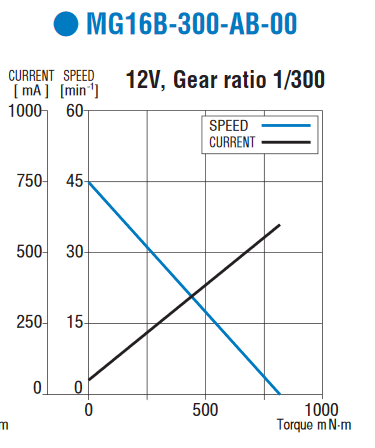

As mentioned in the inline comments, this is based on the stall/holding torque of the motor. The azimuth axis uses closed-loop control which will vary the voltage applied to the motor to achieve the correct elevation, thereby limiting the current. The max and minimum current are found by scaling the stall current down by ratio of required torque to maximum torque. this shifts the blue speed curve towards the left. 

motor_current_max = motor_torque_max/T_max*I_max; % Amps, current required to hold antenna fully closed. Assumes that it will be proportional to ratio between required torque and stall torque at 12V. 
motor_current_min = motor_torque_min/T_max*I_max;

The motor power uses a similar concept, with the scaling applied again to bring the voltage down. 

V*(motor_current_max/I_max) is the voltage required to achieve the current calculated above. 

motor_power_max = V.*(motor_current_max./I_max).*motor_current_max; % W, power draw to hold position. Same as above, voltage scales down by proportion of required current and max current.
motor_power_min = V.*(motor_current_max./I_max).*motor_current_min;
if max(motor_current_max./I_max) > 1
    print("One configuration exceeds motor performance");
end

## Excess lifting torque

The next section, described in inline comments, goes over the process of finding the excess lifting torque and attempts to put that in terms of the weight of the dust cover as it is lifted off the body of the antenna. 

%% Find excess lifiting ability
% assume that lifted mass of cover increases linearly with elevation angle
% the cover will lift up off the ground at a constant rate with repsect to
% the arc length of the swinging edge of the antenna. I will account for
% this with the antenna mass + theta (0 to 90) * max dust cover mass 
%
% see page 130 of sam's logbook
% 
% basically, I've solved the torque balance between the spring torque
% (unstretched angle - elevation angle)*K; the gravity torque on the
% antenna (m*g*L/2*cos(theta); and the weight of the cover. 
% 
% The weight of the cover is modeled as "second winch line" whose tension increases as
% more of it is lifted off the ground. It connects to the edge of the
% antenna, creating a lever arm with length L. As the antenna elevates, 
% more dust cover lifts off the ground, but the angle decreases. The length
% is assumed to be the arc length swept out by the edge of the antenna.
% 
% This final term is W_cover/(pi*L/2)*sin(pi - theta/2)*L*(L/2*theta)
%                   {______} {______} {_______________}{_}{_________}
%                       ^       ^              ^        ^       ^
%               Total Weight    |              |        |       |
%                     total arc length         |        |       |
%                           Contact angle on antenna    |       |
%                                                   Lever Arm   |
%                                                         Arc length @
%                                                         elevation
% Equate everything and solve for W_cover, which is below.

theta = linspace(0, pi/2, 16);
max_dust_weight = zeros(size(K, 1), size(K, 2), length(theta));

for i = 1:length(theta)    
    max_dust_weight(:,:,i) = ((theta0 - theta(i)).*K- m*g*L/2.*cos(theta(i)))*pi/2*L./(sin(pi/2-theta(i)/2)*L^2/2*theta(i));
end


The "danger_disturbance" below is the amount of shock applied perpendicular to the antenna that will cause the winch line to go slack - tension of zero. At this moment, the antenna will oscillate at the very low frequency described above, which is undesireable. The image below shows the derivaiton. 

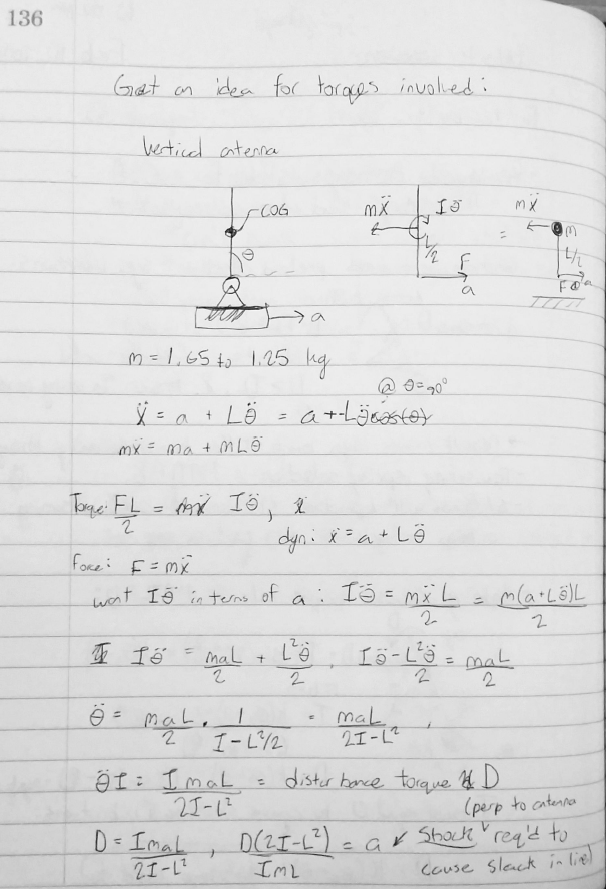


danger_disturbance = (theta0 - pi/2).*K;
slack_shock = danger_disturbance*(2*realI-L^2)/(realI*m*L); % m/s^2, shock perpendicular to antenna req'd to cause slack in line. page 136 of sam's logbook. might be wrong.



## Plotting Performance Plots

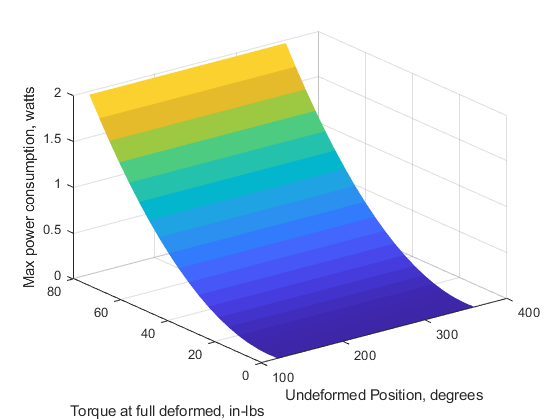

%% Plot stuff
% first plot shows the maximum power consumption for different spring
% consumptions. This is the power consumption to fully compress the spring,
% which is the point of maximum winch tension. This analysis ignore the
% weight of the dust cover. 
s = surf(theta0*180/pi, T, motor_power_max);
xlabel("Undeformed Position, degrees");
ylabel("Torque at full deformed, in-lbs");
zlabel("Max power consumption, watts");
s.EdgeColor = 'none';

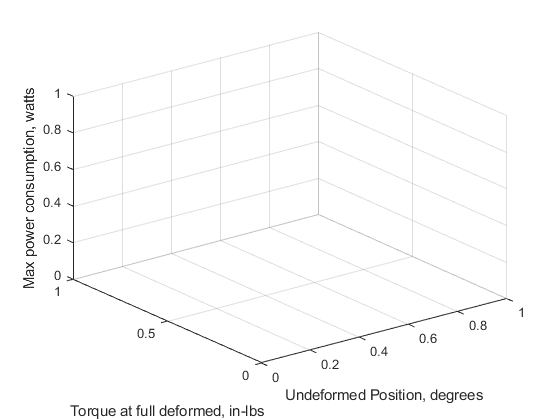

figure(1);
cla;

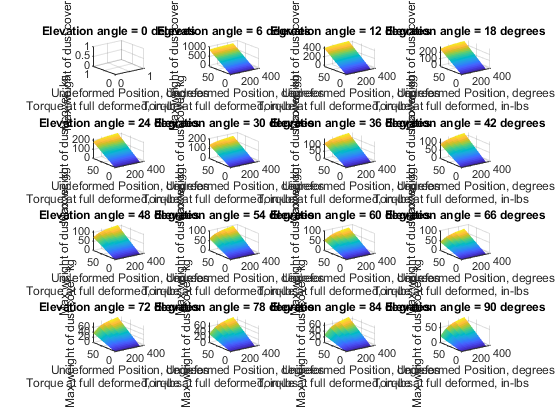

% second plot shows the bandwidth for each spring combination, a simple
% root(K/M) for a torsional setup. A higher bandwidth is better
% Feb 11, 2021: Actually not accurate due to preload in string, omitting
% from output.
% s = surf(theta0*180/pi, T, BW);
% xlabel("Undeformed Position, degrees");
% ylabel("Torque at full deformed, in-lbs");
% zlabel("Mechanical Bandwidth, Hertz");
% s.EdgeColor = 'none';

% the third set of plots shows maximum dust cover weight for each spring
% combination at different elevation angles. Only the 90 degree/vertical
% plot is technically needed, since it offers the most conservative
% estimate for the current parameters. However, I imagine if the geometry
% of the problem changed, or we modeled torque required to lift the dust
% cover differently, you may end up with a different elevation angle being
% the "worst" case. Best to keep the subplots.
% The more dust cover you can lift, the better.

figure(2);
cla
for i = 1:length(theta)
    subplot(length(theta)/4, length(theta)/4, i)
    s = surf(theta0*180/pi, T, max_dust_weight(:,:,i));
    xlabel("Undeformed Position, degrees");
    ylabel("Torque at full deformed, in-lbs");
    zlabel("Max weight of dust cover, kg");
    title("Elevation angle = " + theta(i)*180/pi + " degrees")
    s.EdgeColor = 'none';
end

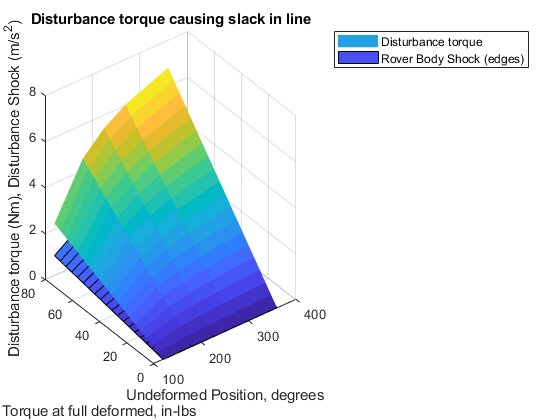


% fouth plot shows "danger disturbance torque" which causes cable to lose
% tension. Causes vibrations, potential tangling. Also shows acceleration
% of rover body req'd to cause loss of tension. 

figure(4);
cla;
s = surf(theta0*180/pi, T, danger_disturbance);
hold on
xlabel("Undeformed Position, degrees");
ylabel("Torque at full deformed, in-lbs");
zlabel("Disturbance torque (Nm), Disturbance Shock (m/s^2)");
title("Disturbance torque causing slack in line")
s.EdgeColor = 'none';
s = surf(theta0*180/pi, T, slack_shock);
legend(["Disturbance torque", "Rover Body Shock (edges)"]);

While the code can be run to show these plots, they are also displayed below. 

## 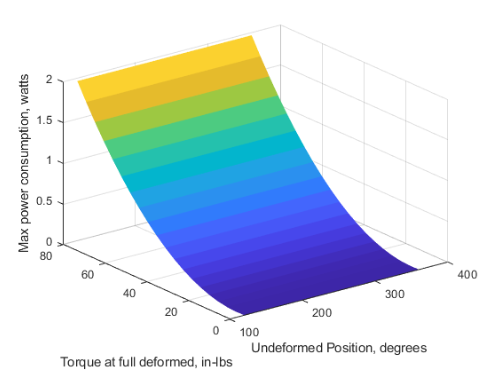

## 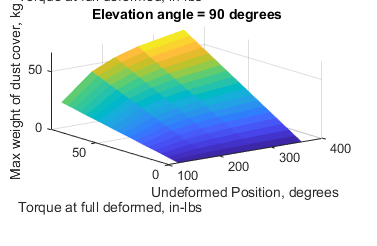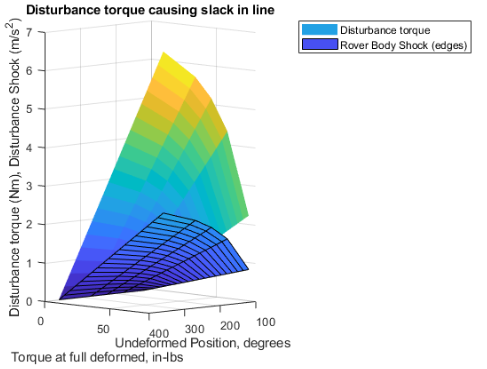

## Selecting a spring

By looking at the plots above, the selected spring (2 at 22.5 in-lbs max torque, 270 degrees of rotation) offered a balance of power consumption under 1 W and excess lifting ability and cable preload.

Once the spring has been selected, the following curve shows its performance over the range of elevation angles.

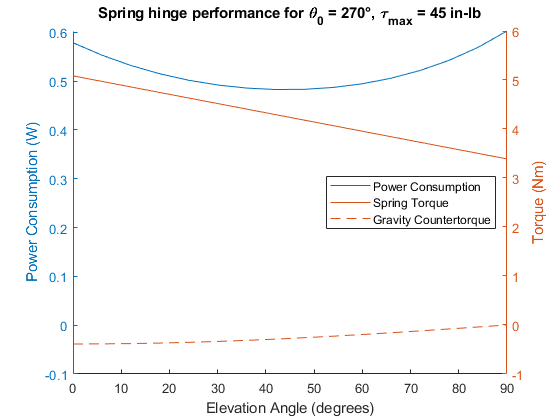

%% 
% fifth plot shows power consumption and disturbance withstance over all
% elevation angles for chosen spring

Spring_angle = 270;
theta0 = Spring_angle*pi/180;
K = 22.5*2*0.11298482933333./theta0;
gravity_torque = -m*g*L/2*cos(theta);
spring_torque = (theta0 - theta).*K;
net_torque = spring_torque + gravity_torque;

tension = net_torque./(L/2*sin(pi/2-theta/2)); %N, 
motor_torque = tension*pulley_radius; % Nm, torque required to hold antenna full closed
motor_current = motor_torque/T_max*I_max; % Amps, current required to hold antenna fully closed. Assumes that it will be proportional to ratio between required torque and stall torque at 12V. 
motor_power = V.*(motor_current./I_max).*motor_current; % W, power draw to hold position. Same as above, voltage scales down by proportion of required current and max current.



figure(5);
cla
hold on
yyaxis left;
h(1) = plot(theta*180/pi, motor_power);
ylabel("Power Consumption (W)");
ylim([-.1 inf])
yyaxis right;
h(2) = plot(theta*180/pi, spring_torque);
h(3) = plot(theta*180/pi, gravity_torque);
xlabel("Elevation Angle (degrees)");
ylabel("Torque (Nm)");
legend(h, ["Power Consumption" ,"Spring Torque", "Gravity Countertorque"], 'Location', 'east');
title(sprintf(["Spring hinge performance for \\theta_0 = %i" + char(176)+ ", \\tau_m_a_x = %i in-lb"], Spring_angle, 45))